clc;
clear;
close all;

%% Step 1: Load Dataset
datasetPath = fullfile('C:\Users\rahul\OneDrive\Desktop\dataset\brain_tumor_dataset'); % Update this path
imds = imageDatastore(datasetPath, ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

disp("Number of images per class:");

Number of images per class:


disp(countEachLabel(imds));

    Label    Count
    _____    _____

     no        98 
     yes      155 



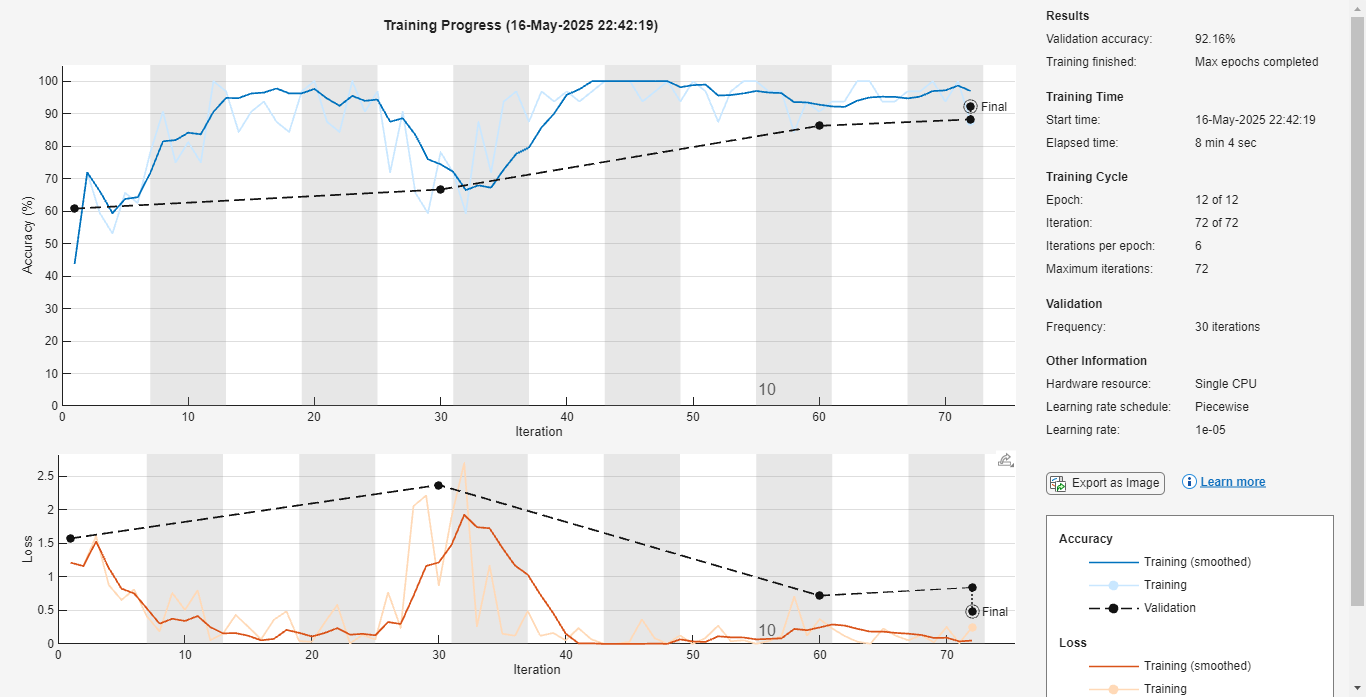


%% Step 2: Split Dataset
[imdsTrain, imdsTest] = splitEachLabel(imds, 0.8, 'randomized');

%% Step 3: Load Pretrained ResNet-18 and Convert to Layer Graph
net = resnet18;
inputSize = net.Layers(1).InputSize;

lgraph = layerGraph(net);

%% Step 4: Replace final layers to adapt to your classes
numClasses = numel(categories(imdsTrain.Labels));

% Remove layers related to classification
lgraph = removeLayers(lgraph, {'fc1000','prob','ClassificationLayer_predictions'});

% Add new layers
newLayers = [
    fullyConnectedLayer(numClasses, 'Name', 'fc', ...
        'WeightLearnRateFactor', 20, 'BiasLearnRateFactor', 20)
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'classoutput')];

lgraph = addLayers(lgraph, newLayers);

% Connect new layers to the graph
lgraph = connectLayers(lgraph, 'pool5', 'fc');

%% Step 5: Define preprocessing and augmentation
imageAugmenter = imageDataAugmenter( ...
    'RandRotation',[-10 10], ...
    'RandXTranslation',[-5 5], ...
    'RandYTranslation',[-5 5], ...
    'RandXScale',[0.9 1.1], ...
    'RandYScale',[0.9 1.1]);

augTrain = augmentedImageDatastore(inputSize(1:2), imdsTrain, ...
    'DataAugmentation', imageAugmenter, ...
    'ColorPreprocessing', 'gray2rgb');

augTest = augmentedImageDatastore(inputSize(1:2), imdsTest, ...
    'ColorPreprocessing', 'gray2rgb');

%% Step 6: Training options
options = trainingOptions('sgdm', ...
    'MiniBatchSize', 32, ...
    'MaxEpochs', 12, ...
    'InitialLearnRate', 1e-3, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropFactor', 0.1, ...
    'LearnRateDropPeriod', 4, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', augTest, ...
    'ValidationFrequency', 30, ...
    'Verbose', false, ...
    'Plots', 'training-progress', ...
    'ValidationPatience', 5);

%% Step 7: Train Network
netTransfer = trainNetwork(augTrain, lgraph, options);


%% Step 8: Evaluate
YPred = classify(netTransfer, augTest);
YTest = imdsTest.Labels;

accuracy = sum(YPred == YTest) / numel(YTest);
fprintf('\nTest Accuracy: %.2f%%\n', accuracy*100);


Test Accuracy: 92.16%


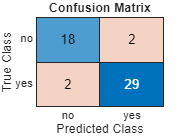


figure;
confusionchart(YTest, YPred);
title('Confusion Matrix');


%% Step 9: Save Model
save('brain_tumor_resnet18_model.mat', 'netTransfer');
disp('Model saved as brain_tumor_resnet18_model.mat');

Model saved as brain_tumor_resnet18_model.mat
